# Miscelanious plots for scitech 2025 PAH paper

clear; clc; close;

## Initialization

c_c = 20

c_c = 20

HM_nc = linspace(-100,100);
HM_c = (HM_nc - c_c .* sign(HM_nc)) .* heaviside(abs(HM_nc) - 20)

HM_c =   -80.0000  -77.9798  -75.9596  -73.9394  -71.9192  -69.8990  -67.8788  -65.8586  -63.8384  -61.8182  -59.7980  -57.7778  -55.7576  -53.7374  -51.7172  -49.6970  -47.6768  -45.6566  -43.6364  -41.6162  -39.5960  -37.5758  -35.5556  -33.5354  -31.5152  -29.4949  -27.4747  -25.4545  -23.4343  -21.4141  -19.3939  -17.3737  -15.3535  -13.3333  -11.3131   -9.2929   -7.2727   -5.2525   -3.2323   -1.2121         0         0         0         0         0         0         0         0         0         0


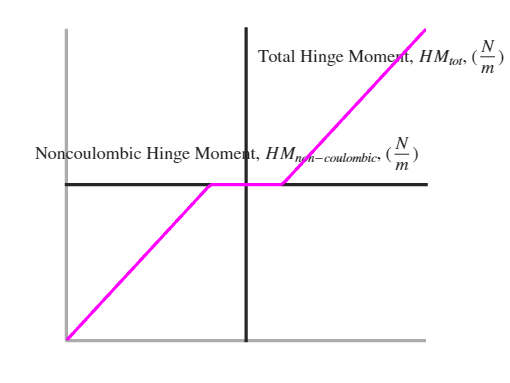


% produce the culomib hinge moment plot
figure;
hold on
plot(HM_nc, HM_c, "m-", "LineWidth",2, "DisplayName", "Total Hinge Moment");
xlabel("Noncoulombic Hinge Moment, $HM_{non-coulombic}$, ($\frac{N}{m}$)",Interpreter="latex");
ylabel("Total Hinge Moment, $HM_{tot}$, ($\frac{N}{m}$)",Interpreter="latex");
%legend("Location","northwest");
set(gca,"LineWidth", 2);
grid on;
% Set axes to cross at zero
ax = gca;
ax.XAxisLocation = 'origin'; ax.YAxisLocation = 'origin';
% Turn off axis numbers
ax.XTick = []; ax.YTick = [];

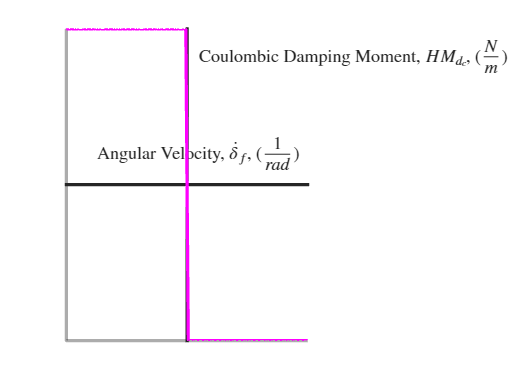



% produce the culomib hinge moment vs rate plot
figure;
hold on
plot(HM_nc, -c_c .* sign(HM_nc), "m-", "LineWidth",2, "DisplayName", "Total Hinge Moment");
xlabel("Angular Velocity, $\dot\delta_f$, ($\frac{1}{rad}$)",Interpreter="latex");
ylabel("Coulombic Damping Moment, $HM_{d_c}$, ($\frac{N}{m}$)",Interpreter="latex");
%legend("Location","northwest");
set(gca,"LineWidth", 2);
grid on;
% Set axes to cross at zero
ax = gca;
ax.XAxisLocation = 'origin'; ax.YAxisLocation = 'origin';
% Turn off axis numbers
ax.XTick = []; ax.YTick = [];

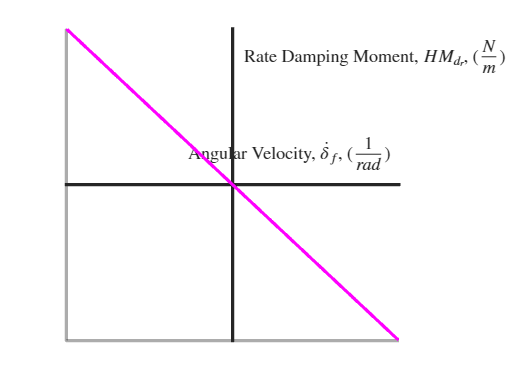


% produce the rate hinge moment plot
figure;
hold on
plot(HM_nc, -c_c *(HM_nc), "m-", "LineWidth",2, "DisplayName", "Total Hinge Moment");
xlabel("Angular Velocity, $\dot\delta_f$, ($\frac{1}{rad}$)",Interpreter="latex");
ylabel("Rate Damping Moment, $HM_{d_r}$, ($\frac{N}{m}$)",Interpreter="latex");
%legend("Location","northwest");
set(gca,"LineWidth", 2);
grid on;
% Set axes to cross at zero
ax = gca;
ax.XAxisLocation = 'origin'; ax.YAxisLocation = 'origin';
% Turn off axis numbers
ax.XTick = []; ax.YTick = [];

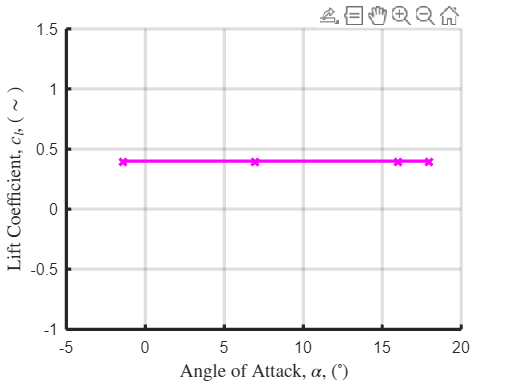


% produce C_l vs Alpha plot
fileName_neutralCamber = "KL_sexy_sexy"; % filename of airfoil with the neutral camber
airfoil_neutralCamber = ReadAirfoil(fileName_neutralCamber);
[alphas_neutralCamber, c_ls_neutralCamber] = airfoil_neutralCamber.getPlotPoints;
figure;
hold on
plot(rad2deg(alphas_neutralCamber), .4* ones(length(alphas_neutralCamber)),"m-x", "LineWidth",2, "DisplayName","Slightly Cambered airfoil");
xlabel("Angle of Attack, $\alpha$, ($^\circ$)",Interpreter="latex", FontSize=12);
ylabel("Lift Coefficient, $c_{l}$, ($\sim$)",Interpreter="latex", FontSize=12);
%legend("Location","northwest");
set(gca,"LineWidth", 2);
grid on;